# Expansion of the Universe

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1 

Find and plot the size of the universe out to 13.1 times its current age. 

*Remember to define your ODE function at the bottom of the script. *

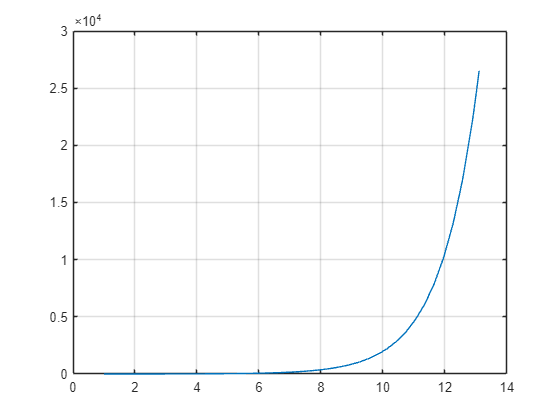

tRange = [1 13.1];
Y0 = [1; 1];
[tSol, YSol] = ode45(@expandingUniverse, tRange, Y0);
plot(tSol, YSol(:, 1))
grid on

## Task 2

Find and plot the size of the universe out to 13.1 times its current age. 

*Remember to define your ODE function at the bottom of the script. *

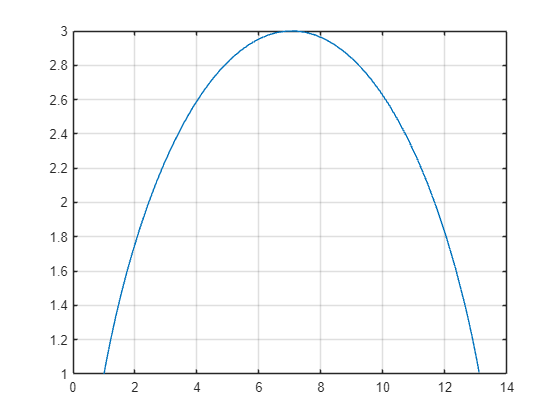

tRange = [1 13.1];
Y0 = [1; 1];
[tSol, YSol] = ode45(@contractingUniverse, tRange, Y0);
plot(tSol, YSol(:, 1))
grid on

## Task 1 (continued)

Define the ODE function for   where  and  

function dYdt = expandingUniverse(t, Y)
    % Extract size of universe, R from first element of Y
    R = Y(1);
    
    % Extract the velocity of the expansion of the universe, v from the second
    %element of Y
    v = Y(2);
    
    % Set the matter density 
    omegaM = 0.3;
    
    % Set the dark energy density
    omegaDE = 0.7;
    
    % Define dRdt
    dRdt = v;
    
    % Define dvdt
    dvdt = -0.5*omegaM/R^2 + omegaDE*R;
    
    % Store derivatives in column vector dYdt 
    dYdt = [dRdt; dvdt];
end

## Task 2 (continued)

Define the ODE function for   where  and  

function dYdt = contractingUniverse(t, Y)
    % Extract size of universe, R from first element of Y
    R = Y(1);
    
    % Extract the velocity of the expansion of the universe, v from the second
    %element of Y
    v = Y(2);
    
    % Set the matter density 
    omegaM = 1.5;
    
    % Set the dark energy density
    omegaDE = 0.0;
    
    % Define dRdt
    dRdt = v;
    
    % Define dvdt
    dvdt = -0.5*omegaM/R^2 + omegaDE*R;
    
    % Store derivatives in column vector dYdt 
    dYdt = [dRdt; dvdt];
end